# **Effective Solar House Design**

*Authors: *Drew Pang and Kelly Stellmacher

## Question:

Traditional houses attempt to separate the temperature-controlled air from the outside air but add windows to let natural light. While these homes have gotten more energy efficient due to advances in insulation, solar houses can be more energy efficient. By contrast, solar homes attempt to heat themselves through large windows facing south. During Winter, the sun shines into the house and radiates heat energy off of the floor. However, during the Summer when the sun is higher, the soffit blocks the sun from entering the already warm house. 

 We can use thermodynamics to model a solar house to estimate the effects of parameters. Let's take a look at the specific solar house we are modeling:

Question: What thickness of insulation in a solar house in Columbus, Ohio during Winter would maintain a minimum internal temperature over time?

Why is this interesting? We are asking a design question, and through our model, we will be able to determine the effects of the thickness of our walls. This may help architects and homeowners looking to design and build solar houses.

## **Method/model:**

We are going to answer our question by tracking the flow of energy from the sun into the floor, then into the room and out the walls. This will allow us to determine the change in temperature of the room over time. We began with energy transferring directly from the sun into the room, but advised to introduce an intermediary stock that stores the energy from the sun before emmiting it into the room. We also grappled with the possibility of adding another convective flow from the walls of the house to the outside air, but decided to begin by only implementing a conduction flow from the rom to the outside air through the walls. 

We developed the following scematic diagram:

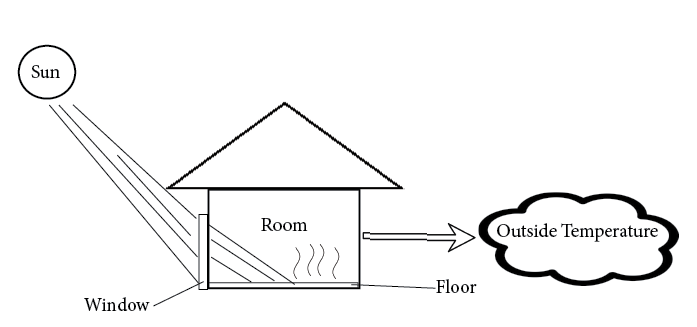

Where energy radiates from the sun, through the window of the house, into the floor, and then conducts from the floor into the air contained in the house. The energy then leaves the house via convecting through the walls. 

From the scematic, we developed the following stock and flow diagram:

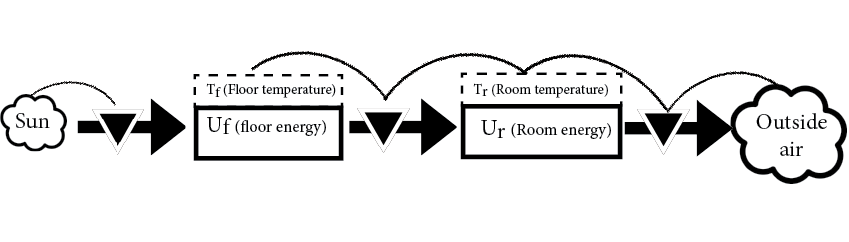

Where energy flows from the sun to Uf (the stock of energy in the floor), then to Ur (the stock of energy in the room), then out the room into the outside air. The flow from the sun to the floor is radiation, the flow from the floor to the room is convection, and the flow from the room to the outside air is conduction. 

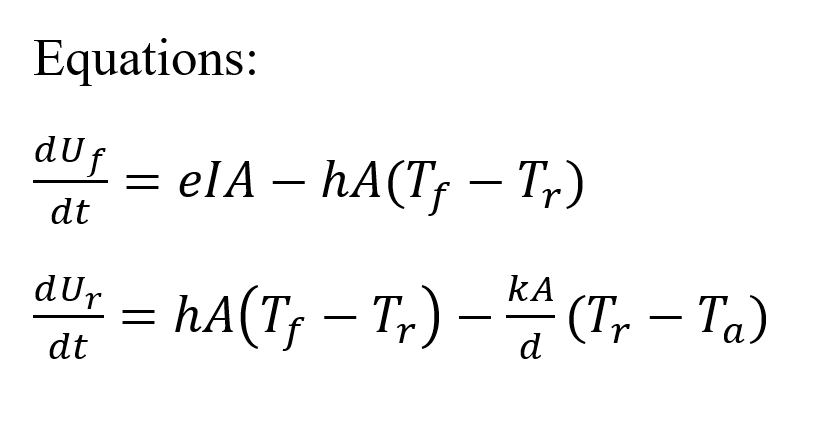

Through research into the different parameters of the system, we managed to gain reliable approximations for all of the factors contributing to our model. The parameter settings needed to be revised multiple times for the final values to be settled on.  

**Parameters**: 

- Tf_0 = 293 K, floor starting temperature

- Tr_0 = 293 K, house int starting temperature

- Ta = 263.56 K, environment temperature$^1$

- w = 10m, sidelength of house

- wt = 0.1-0.5m, thickness of walls  

- wf = 0.05715m, thickness of floor$^2
$

- I = 170.14 W/m^2 incident solar radiation$^3

$ 

- e = 0.473 J/m^2, emmisivity of oak floor$^4$ 

- h_a = 0.026 W/m, thermal conductivity of air$^5$

- h_w = 0.05 W/m, thermal conductivity of insulation walls$^6$ 

- h_f = 0.170 W/m, thermal conductivity of wood floor$^7
$

- s_f = 1850 J/kg C, specific heat of wood floor$^8$

- s_a = 1005 J/kg C, specific heat of air$^9$

- d = 1.293 kg/m^3, density of air$^{10}$ 

- d_f = 745 kg/m^3, density of wood floor$^{11}$ 

$^1$ (*Columbus December Weather, Average Temperature (Ohio, United States) - Weather Spark*, n.d.)

$^2
$(*What Is the Best Thickness for Wood Flooring?*, n.d.)

$^3

$(*Data.GISS: Insolation at Specified Location*, n.d.)

$^4$(*Polytec - Decorative Surfaces and Doors for Kitchens, Laundries, Wardrobes, Furniture, and Commercial Use.*, n.d.)

$^5$(*Thermal Conductivity of Common Materials | Neutrium*, n.d.)

$^6$(“Thermal Conductivity of Insulation - Steady State & Transient Method,” 2019)

$^7
$(*Thermal Conductivity of Common Materials | Neutrium*, n.d.)

$^8$(Radmanović et al., 2014)

$^9
$(*Specific Heat Capacities of Air - (Updated 7/26/08)*, n.d.)

$^{10}$(*Air Density | Glossary*, n.d.)

$^{11}$(*Density of Wood in Kg/M3, g/Cm3, Lb/Ft3 – the Ultimate Guide - Matmatch*, n.d.)

**Assumptions** for our model inlcude:

- The structural integrity of the house will not be jepordized based on the material the walls are composed of. 

- The roof is made of the same material as the walls. 

- The aperture of the window will remain constant.

- The Sun zenith angle remains the same.

- The house is empty: no people or furniture is present to alter energy content of the room

- There is nothing obstructing the sunlight from reaching the house. 

- The heat conducting through the window is the same per unit of area as the walls. 

- The aperture of the sun remains constant

- The aperture of the sun is situated such that the entire floor is reached by the sun

All of these assumptions are made in order to keep this model simple and possible to program. However, if we wished to increase the accuracy, we could take our assumptions and act on them. For example, if we wanted to make the house realistically liveable, we would have to account for structural integrity and openings where people can enter and exit. 

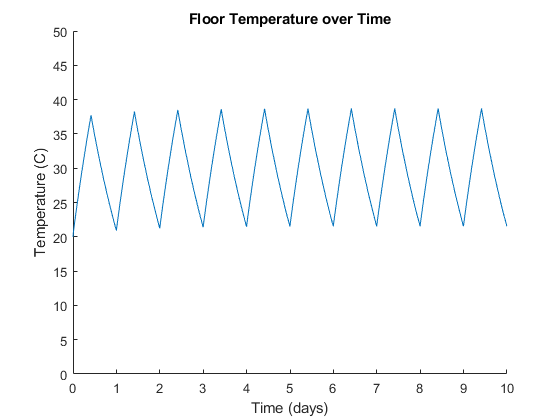

figure(1);
clf; hold on;
wt = 0.3;
[Tt,Dt] = solar_house_day_night(wt);
plot(Tt/(24*3600),Dt(:,1));

title('Floor Temperature over Time');
xlabel('Time (days)')
ylabel('Temperature (C)')
ylim([0 50])

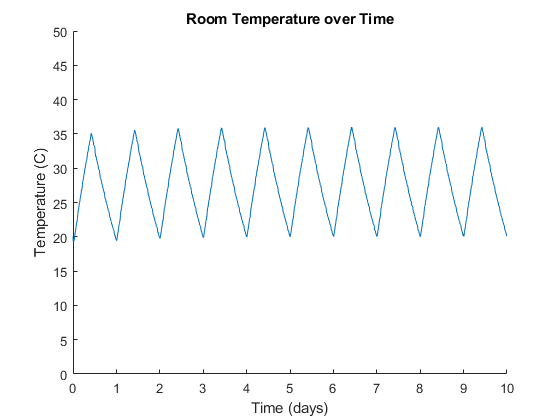

figure(2)
clf; hold on;
wt = 0.3;
[Tt,Dt] = solar_house_day_night(wt);
plot(Tt/(24*3600),Dt (:,2));
title('Room Temperature over Time');
xlabel('Time (days)')
ylabel('Temperature (C)')
ylim([0 50])

**Model Verification:**

Verifying this model is difficult because the total energy is not able to be tracked, as it is contained in stocks that are not fully monitored. For example, the energy leaving the room into the outside air is contained in the walls before it is released, leading to an unknown stock. 

**Model validation:**

If we had more time and resources for this project, we could validate the results by constructing a miniature model house with the materials we specified, setting up a controllable heat source, then monitor the change in temperature over time.  

## **Results:**

figure(1);
clf; hold on;
title('Floor Temperature over Time');
xlabel('Time (days)')
ylabel('Temperature (C)')

for wt = 0.1:0.1:0.5
    
    [Tt,Dt] = solar_house_day_night(wt);
    plot(Tt/(24*3600),Dt(:,1));
end

energyIntoFloor = 7.4616e+03

energyOutofFloor = 0

energyIntoRoom = 0

EnergyOutofRoom = 7.3600e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 7.1401e+03

energyIntoRoom = 7.1401e+03

EnergyOutofRoom = 6.3405e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 1.9795e+03

energyIntoRoom = 1.9795e+03

EnergyOutofRoom = 7.1023e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 1.3554e+05

energyIntoRoom = 1.3554e+05

EnergyOutofRoom = -1.2307e+04

energyIntoFloor = 7.4616e+03

energyOutofFloor = 5.9161e+05

energyIntoRoom = 5.9161e+05

EnergyOutofRoom = -7.8742e+04

energyIntoFloor = 7.4616e+03

energyOutofFloor = 1.0341e+06

energyIntoRoom = 1.0341e+06

EnergyOutofRoom = -1.4319e+05

energyIntoFloor = 7.4616e+03

energyOutofFloor = -1.4832e+05

energyIntoRoom = -1.4832e+05

EnergyOutofRoom = 2.9068e+04

energyIntoFloor = 7.4616e+03

energyOutofFloor = 2.0141e+03

energyIntoRoom = 2.0141e+03

EnergyOutofRoom = 7.0724e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 2.3265e+03

energyIntoRoom = 2.3265e+03

EnergyOutofRoom = 7.0298e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 6.9113e+03

energyIntoRoom = 6.9113e+03

EnergyOutofRoom = 6.3763e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 1.2826e+04

energyIntoRoom = 1.2826e+04

EnergyOutofRoom = 5.5172e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 1.3976e+04

energyIntoRoom = 1.3976e+04

EnergyOutofRoom = 5.3528e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 5.1094e+03

energyIntoRoom = 5.1094e+03

EnergyOutofRoom = 6.6445e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 5.5603e+03

energyIntoRoom = 5.5603e+03

EnergyOutofRoom = 6.5845e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 5.6314e+03

energyIntoRoom = 5.6314e+03

EnergyOutofRoom = 6.5770e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 6.6584e+03

energyIntoRoom = 6.6584e+03

EnergyOutofRoom = 6.4414e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 7.9737e+03

energyIntoRoom = 7.9737e+03

EnergyOutofRoom = 6.2523e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 8.2311e+03

energyIntoRoom = 8.2311e+03

EnergyOutofRoom = 6.2179e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 6.2614e+03

energyIntoRoom = 6.2614e+03

EnergyOutofRoom = 6.5048e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 6.4232e+03

energyIntoRoom = 6.4232e+03

EnergyOutofRoom = 6.4900e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 6.4202e+03

energyIntoRoom = 6.4202e+03

EnergyOutofRoom = 6.4947e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 7.0276e+03

energyIntoRoom = 7.0276e+03

EnergyOutofRoom = 6.4275e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 8.3038e+03

energyIntoRoom = 8.3038e+03

EnergyOutofRoom = 6.2453e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 8.7202e+03

energyIntoRoom = 8.7202e+03

EnergyOutofRoom = 6.1893e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 6.5483e+03

energyIntoRoom = 6.5483e+03

EnergyOutofRoom = 6.5057e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 6.5990e+03

energyIntoRoom = 6.5990e+03

EnergyOutofRoom = 6.5090e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 6.5949e+03

energyIntoRoom = 6.5949e+03

EnergyOutofRoom = 6.5149e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 6.8632e+03

energyIntoRoom = 6.8632e+03

EnergyOutofRoom = 6.5019e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 7.5040e+03

energyIntoRoom = 7.5040e+03

EnergyOutofRoom = 6.4132e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 7.7987e+03

energyIntoRoom = 7.7987e+03

EnergyOutofRoom = 6.3759e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 6.6128e+03

energyIntoRoom = 6.6128e+03

EnergyOutofRoom = 6.5486e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 6.6596e+03

energyIntoRoom = 6.6596e+03

EnergyOutofRoom = 6.5552e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 6.6498e+03

energyIntoRoom = 6.6498e+03

EnergyOutofRoom = 6.5632e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 7.0378e+03

energyIntoRoom = 7.0378e+03

EnergyOutofRoom = 6.5390e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 8.1190e+03

energyIntoRoom = 8.1190e+03

EnergyOutofRoom = 6.3871e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 8.8315e+03

energyIntoRoom = 8.8315e+03

EnergyOutofRoom = 6.2903e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 6.5509e+03

energyIntoRoom = 6.5509e+03

EnergyOutofRoom = 6.6225e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 6.6928e+03

energyIntoRoom = 6.6928e+03

EnergyOutofRoom = 6.6149e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 6.6393e+03

energyIntoRoom = 6.6393e+03

EnergyOutofRoom = 6.6290e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 8.0862e+03

energyIntoRoom = 8.0862e+03

EnergyOutofRoom = 6.4497e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 1.2388e+04

energyIntoRoom = 1.2388e+04

EnergyOutofRoom = 5.8284e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 1.5359e+04

energyIntoRoom = 1.5359e+04

EnergyOutofRoom = 5.4024e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 6.0591e+03

energyIntoRoom = 6.0591e+03

EnergyOutofRoom = 6.7573e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 6.6607e+03

energyIntoRoom = 6.6607e+03

EnergyOutofRoom = 6.6166e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 6.6411e+03

energyIntoRoom = 6.6411e+03

EnergyOutofRoom = 6.6244e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 7.3175e+03

energyIntoRoom = 7.3175e+03

EnergyOutofRoom = 6.5504e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 9.0620e+03

energyIntoRoom = 9.0620e+03

EnergyOutofRoom = 6.3005e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 9.9178e+03

energyIntoRoom = 9.9178e+03

EnergyOutofRoom = 6.1812e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 6.6067e+03

energyIntoRoom = 6.6067e+03

EnergyOutofRoom = 6.6635e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 6.7046e+03

energyIntoRoom = 6.7046e+03

EnergyOutofRoom = 6.6589e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 6.6875e+03

energyIntoRoom = 6.6875e+03

EnergyOutofRoom = 6.6660e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 7.2890e+03

energyIntoRoom = 7.2890e+03

EnergyOutofRoom = 6.6017e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 8.8376e+03

energyIntoRoom = 8.8376e+03

EnergyOutofRoom = 6.3802e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 9.5973e+03

energyIntoRoom = 9.5973e+03

EnergyOutofRoom = 6.2745e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 6.6586e+03

energyIntoRoom = 6.6586e+03

EnergyOutofRoom = 6.7026e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 6.7523e+03

energyIntoRoom = 6.7523e+03

EnergyOutofRoom = 6.6987e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 6.7316e+03

energyIntoRoom = 6.7316e+03

EnergyOutofRoom = 6.7065e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 7.3869e+03

energyIntoRoom = 7.3869e+03

EnergyOutofRoom = 6.6347e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 9.1433e+03

energyIntoRoom = 9.1433e+03

EnergyOutofRoom = 6.3830e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 1.0090e+04

energyIntoRoom = 1.0090e+04

EnergyOutofRoom = 6.2501e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 6.6503e+03

energyIntoRoom = 6.6503e+03

EnergyOutofRoom = 6.7513e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 6.7764e+03

energyIntoRoom = 6.7764e+03

EnergyOutofRoom = 6.7422e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 6.7452e+03

energyIntoRoom = 6.7452e+03

EnergyOutofRoom = 6.7513e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 7.6630e+03

energyIntoRoom = 7.6630e+03

EnergyOutofRoom = 6.6403e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 1.0160e+04

energyIntoRoom = 1.0160e+04

EnergyOutofRoom = 6.2805e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 1.1527e+04

energyIntoRoom = 1.1527e+04

EnergyOutofRoom = 6.0862e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 6.6062e+03

energyIntoRoom = 6.6062e+03

EnergyOutofRoom = 6.8031e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 6.7765e+03

energyIntoRoom = 6.7765e+03

EnergyOutofRoom = 6.7866e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 6.7398e+03

energyIntoRoom = 6.7398e+03

EnergyOutofRoom = 6.7959e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 7.8499e+03

energyIntoRoom = 7.8499e+03

EnergyOutofRoom = 6.6543e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 1.0781e+04

energyIntoRoom = 1.0781e+04

EnergyOutofRoom = 6.2308e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 1.2253e+04

energyIntoRoom = 1.2253e+04

EnergyOutofRoom = 6.0207e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 6.6398e+03

energyIntoRoom = 6.6398e+03

EnergyOutofRoom = 6.8385e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 6.7975e+03

energyIntoRoom = 6.7975e+03

EnergyOutofRoom = 6.8229e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 6.7706e+03

energyIntoRoom = 6.7706e+03

EnergyOutofRoom = 6.8304e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 7.6801e+03

energyIntoRoom = 7.6801e+03

EnergyOutofRoom = 6.7158e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 9.9900e+03

energyIntoRoom = 9.9900e+03

EnergyOutofRoom = 6.3824e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 1.1051e+04

energyIntoRoom = 1.1051e+04

EnergyOutofRoom = 6.2318e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 6.7487e+03

energyIntoRoom = 6.7487e+03

EnergyOutofRoom = 6.8585e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 6.8574e+03

energyIntoRoom = 6.8574e+03

EnergyOutofRoom = 6.8498e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 6.8390e+03

energyIntoRoom = 6.8390e+03

EnergyOutofRoom = 6.8559e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 7.4752e+03

energyIntoRoom = 7.4752e+03

EnergyOutofRoom = 6.7804e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 9.0947e+03

energyIntoRoom = 9.0947e+03

EnergyOutofRoom = 6.5475e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 9.8521e+03

energyIntoRoom = 9.8521e+03

EnergyOutofRoom = 6.4410e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 6.8212e+03

energyIntoRoom = 6.8212e+03

EnergyOutofRoom = 6.8825e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 6.9075e+03

energyIntoRoom = 6.9075e+03

EnergyOutofRoom = 6.8772e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 6.8891e+03

energyIntoRoom = 6.8891e+03

EnergyOutofRoom = 6.8834e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 7.4679e+03

energyIntoRoom = 7.4679e+03

EnergyOutofRoom = 6.8168e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 9.0035e+03

energyIntoRoom = 9.0035e+03

EnergyOutofRoom = 6.5962e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 9.8017e+03

energyIntoRoom = 9.8017e+03

EnergyOutofRoom = 6.4838e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 6.8303e+03

energyIntoRoom = 6.8303e+03

EnergyOutofRoom = 6.9166e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 6.9340e+03

energyIntoRoom = 6.9340e+03

EnergyOutofRoom = 6.9088e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 6.9071e+03

energyIntoRoom = 6.9071e+03

EnergyOutofRoom = 6.9163e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 7.6824e+03

energyIntoRoom = 7.6824e+03

EnergyOutofRoom = 6.8209e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 9.8090e+03

energyIntoRoom = 9.8090e+03

EnergyOutofRoom = 6.5142e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 1.0994e+04

energyIntoRoom = 1.0994e+04

EnergyOutofRoom = 6.3454e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 6.7760e+03

energyIntoRoom = 6.7760e+03

EnergyOutofRoom = 6.9599e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 6.9316e+03

energyIntoRoom = 6.9316e+03

EnergyOutofRoom = 6.9438e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 6.8931e+03

energyIntoRoom = 6.8931e+03

EnergyOutofRoom = 6.9527e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 7.9908e+03

energyIntoRoom = 7.9908e+03

EnergyOutofRoom = 6.8088e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 1.0960e+04

energyIntoRoom = 1.0960e+04

EnergyOutofRoom = 6.3790e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 1.2531e+04

energyIntoRoom = 1.2531e+04

EnergyOutofRoom = 6.1536e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 6.7439e+03

energyIntoRoom = 6.7439e+03

EnergyOutofRoom = 6.9967e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 6.9223e+03

energyIntoRoom = 6.9223e+03

EnergyOutofRoom = 6.9765e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 6.8882e+03

energyIntoRoom = 6.8882e+03

EnergyOutofRoom = 6.9843e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 7.9608e+03

energyIntoRoom = 7.9608e+03

EnergyOutofRoom = 6.8420e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 1.0729e+04

energyIntoRoom = 1.0729e+04

EnergyOutofRoom = 6.4412e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 1.2031e+04

energyIntoRoom = 1.2031e+04

EnergyOutofRoom = 6.2544e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 6.8355e+03

energyIntoRoom = 6.8355e+03

EnergyOutofRoom = 7.0114e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 6.9655e+03

energyIntoRoom = 6.9655e+03

EnergyOutofRoom = 6.9977e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 6.9440e+03

energyIntoRoom = 6.9440e+03

EnergyOutofRoom = 7.0035e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 7.6781e+03

energyIntoRoom = 7.6781e+03

EnergyOutofRoom = 6.9094e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 9.5308e+03

energyIntoRoom = 9.5308e+03

EnergyOutofRoom = 6.6417e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 1.0366e+04

energyIntoRoom = 1.0366e+04

EnergyOutofRoom = 6.5228e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 6.9336e+03

energyIntoRoom = 6.9336e+03

EnergyOutofRoom = 7.0229e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 6.9951e+03

energyIntoRoom = 6.9951e+03

EnergyOutofRoom = 7.0177e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 6.9957e+03

energyIntoRoom = 6.9957e+03

EnergyOutofRoom = 7.0195e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 7.2103e+03

energyIntoRoom = 7.2103e+03

EnergyOutofRoom = 6.9975e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 7.6397e+03

energyIntoRoom = 7.6397e+03

EnergyOutofRoom = 6.9365e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 7.7710e+03

energyIntoRoom = 7.7710e+03

EnergyOutofRoom = 6.9194e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 7.0516e+03

energyIntoRoom = 7.0516e+03

EnergyOutofRoom = 7.0242e+03

energyIntoFloor = 0

energyOutofFloor = 7.0516e+03

energyIntoRoom = 7.0516e+03

EnergyOutofRoom = 7.0242e+03

energyIntoFloor = 0

energyOutofFloor = 5.6661e+03

energyIntoRoom = 5.6661e+03

EnergyOutofRoom = 7.0295e+03

energyIntoFloor = 0

energyOutofFloor = 7.0932e+03

energyIntoRoom = 7.0932e+03

EnergyOutofRoom = 6.7288e+03

energyIntoFloor = 0

energyOutofFloor = -4.0775e+04

energyIntoRoom = -4.0775e+04

EnergyOutofRoom = 1.3242e+04

energyIntoFloor = 0

energyOutofFloor = -2.3279e+05

energyIntoRoom = -2.3279e+05

EnergyOutofRoom = 4.1134e+04

energyIntoFloor = 0

energyOutofFloor = -5.1764e+05

energyIntoRoom = -5.1764e+05

EnergyOutofRoom = 8.2537e+04

energyIntoFloor = 0

energyOutofFloor = 1.6902e+05

energyIntoRoom = 1.6902e+05

EnergyOutofRoom = -1.7497e+04

energyIntoFloor = 0

energyOutofFloor = 6.6806e+03

energyIntoRoom = 6.6806e+03

EnergyOutofRoom = 7.0257e+03

energyIntoFloor = 0

energyOutofFloor = 6.6471e+03

energyIntoRoom = 6.6471e+03

EnergyOutofRoom = 7.0046e+03

energyIntoFloor = 0

energyOutofFloor = 5.5466e+03

energyIntoRoom = 5.5466e+03

EnergyOutofRoom = 7.0357e+03

energyIntoFloor = 0

energyOutofFloor = 3.6793e+03

energyIntoRoom = 3.6793e+03

EnergyOutofRoom = 7.2849e+03

energyIntoFloor = 0

energyOutofFloor = 3.1743e+03

energyIntoRoom = 3.1743e+03

EnergyOutofRoom = 7.3301e+03

energyIntoFloor = 0

energyOutofFloor = 6.1823e+03

energyIntoRoom = 6.1823e+03

EnergyOutofRoom = 6.8919e+03

energyIntoFloor = 0

energyOutofFloor = 6.0856e+03

energyIntoRoom = 6.0856e+03

EnergyOutofRoom = 6.8551e+03

energyIntoFloor = 0

energyOutofFloor = 6.0638e+03

energyIntoRoom = 6.0638e+03

EnergyOutofRoom = 6.8332e+03

energyIntoFloor = 0

energyOutofFloor = 5.7936e+03

energyIntoRoom = 5.7936e+03

EnergyOutofRoom = 6.7474e+03

energyIntoFloor = 0

energyOutofFloor = 5.4561e+03

energyIntoRoom = 5.4561e+03

EnergyOutofRoom = 6.7745e+03

energyIntoFloor = 0

energyOutofFloor = 5.3512e+03

energyIntoRoom = 5.3512e+03

EnergyOutofRoom = 6.7624e+03

energyIntoFloor = 0

energyOutofFloor = 5.8722e+03

energyIntoRoom = 5.8722e+03

EnergyOutofRoom = 6.6865e+03

energyIntoFloor = 0

energyOutofFloor = 5.7846e+03

energyIntoRoom = 5.7846e+03

EnergyOutofRoom = 6.6095e+03

energyIntoFloor = 0

energyOutofFloor = 5.7568e+03

energyIntoRoom = 5.7568e+03

EnergyOutofRoom = 6.5699e+03

energyIntoFloor = 0

energyOutofFloor = 5.4360e+03

energyIntoRoom = 5.4360e+03

EnergyOutofRoom = 6.3993e+03

energyIntoFloor = 0

energyOutofFloor = 4.9724e+03

energyIntoRoom = 4.9724e+03

EnergyOutofRoom = 6.4287e+03

energyIntoFloor = 0

energyOutofFloor = 4.6805e+03

energyIntoRoom = 4.6805e+03

EnergyOutofRoom = 6.4241e+03

energyIntoFloor = 0

energyOutofFloor = 5.5603e+03

energyIntoRoom = 5.5603e+03

EnergyOutofRoom = 6.2962e+03

energyIntoFloor = 0

energyOutofFloor = 5.4270e+03

energyIntoRoom = 5.4270e+03

EnergyOutofRoom = 6.2061e+03

energyIntoFloor = 0

energyOutofFloor = 5.4142e+03

energyIntoRoom = 5.4142e+03

EnergyOutofRoom = 6.1550e+03

energyIntoFloor = 0

energyOutofFloor = 4.5112e+03

energyIntoRoom = 4.5112e+03

EnergyOutofRoom = 6.0237e+03

energyIntoFloor = 0

energyOutofFloor = 2.2205e+03

energyIntoRoom = 2.2205e+03

EnergyOutofRoom = 6.3112e+03

energyIntoFloor = 0

energyOutofFloor = 309.4067

energyIntoRoom = 309.4067

EnergyOutofRoom = 6.5331e+03

energyIntoFloor = 0

energyOutofFloor = 5.6443e+03

energyIntoRoom = 5.6443e+03

EnergyOutofRoom = 5.7566e+03

energyIntoFloor = 0

energyOutofFloor = 5.1501e+03

energyIntoRoom = 5.1501e+03

EnergyOutofRoom = 5.7453e+03

energyIntoFloor = 0

energyOutofFloor = 5.2862e+03

energyIntoRoom = 5.2862e+03

EnergyOutofRoom = 5.6850e+03

energyIntoFloor = 0

energyOutofFloor = 1.0174e+03

energyIntoRoom = 1.0174e+03

EnergyOutofRoom = 6.1057e+03

energyIntoFloor = 0

energyOutofFloor = -1.1093e+04

energyIntoRoom = -1.1093e+04

EnergyOutofRoom = 7.8346e+03

energyIntoFloor = 0

energyOutofFloor = -1.8846e+04

energyIntoRoom = -1.8846e+04

EnergyOutofRoom = 8.9206e+03

energyIntoFloor = 0

energyOutofFloor = 6.4520e+03

energyIntoRoom = 6.4520e+03

EnergyOutofRoom = 5.2354e+03

energyIntoFloor = 0

energyOutofFloor = 5.3255e+03

energyIntoRoom = 5.3255e+03

EnergyOutofRoom = 5.7493e+03

energyIntoFloor = 0

energyOutofFloor = 5.3256e+03

energyIntoRoom = 5.3256e+03

EnergyOutofRoom = 5.7229e+03

energyIntoFloor = 0

energyOutofFloor = 4.0600e+03

energyIntoRoom = 4.0600e+03

EnergyOutofRoom = 5.7759e+03

energyIntoFloor = 0

energyOutofFloor = 1.4095e+03

energyIntoRoom = 1.4095e+03

EnergyOutofRoom = 6.1389e+03

energyIntoFloor = 0

energyOutofFloor = 460.1477

energyIntoRoom = 460.1477

EnergyOutofRoom = 6.2485e+03

energyIntoFloor = 0

energyOutofFloor = 5.0381e+03

energyIntoRoom = 5.0381e+03

EnergyOutofRoom = 5.5817e+03

energyIntoFloor = 0

energyOutofFloor = 4.9261e+03

energyIntoRoom = 4.9261e+03

EnergyOutofRoom = 5.5464e+03

energyIntoFloor = 0

energyOutofFloor = 4.9118e+03

energyIntoRoom = 4.9118e+03

EnergyOutofRoom = 5.5232e+03

energyIntoFloor = 0

energyOutofFloor = 4.5119e+03

energyIntoRoom = 4.5119e+03

EnergyOutofRoom = 5.4553e+03

energyIntoFloor = 0

energyOutofFloor = 3.8111e+03

energyIntoRoom = 3.8111e+03

EnergyOutofRoom = 5.5352e+03

energyIntoFloor = 0

energyOutofFloor = 3.5490e+03

energyIntoRoom = 3.5490e+03

EnergyOutofRoom = 5.5458e+03

energyIntoFloor = 0

energyOutofFloor = 4.7377e+03

energyIntoRoom = 4.7377e+03

EnergyOutofRoom = 5.3727e+03

energyIntoFloor = 0

energyOutofFloor = 4.6574e+03

energyIntoRoom = 4.6574e+03

EnergyOutofRoom = 5.3147e+03

energyIntoFloor = 0

energyOutofFloor = 4.6392e+03

energyIntoRoom = 4.6392e+03

EnergyOutofRoom = 5.2834e+03

energyIntoFloor = 0

energyOutofFloor = 4.3010e+03

energyIntoRoom = 4.3010e+03

EnergyOutofRoom = 5.1638e+03

energyIntoFloor = 0

energyOutofFloor = 3.6979e+03

energyIntoRoom = 3.6979e+03

EnergyOutofRoom = 5.2219e+03

energyIntoFloor = 0

energyOutofFloor = 3.3437e+03

energyIntoRoom = 3.3437e+03

EnergyOutofRoom = 5.2369e+03

energyIntoFloor = 0

energyOutofFloor = 4.4995e+03

energyIntoRoom = 4.4995e+03

EnergyOutofRoom = 5.0688e+03

energyIntoFloor = 0

energyOutofFloor = 4.3820e+03

energyIntoRoom = 4.3820e+03

EnergyOutofRoom = 5.0044e+03

energyIntoFloor = 0

energyOutofFloor = 4.3786e+03

energyIntoRoom = 4.3786e+03

EnergyOutofRoom = 4.9654e+03

energyIntoFloor = 0

energyOutofFloor = 3.5638e+03

energyIntoRoom = 3.5638e+03

EnergyOutofRoom = 4.8880e+03

energyIntoFloor = 0

energyOutofFloor = 1.4778e+03

energyIntoRoom = 1.4778e+03

EnergyOutofRoom = 5.1574e+03

energyIntoFloor = 0

energyOutofFloor = -91.5570

energyIntoRoom = -91.5570

EnergyOutofRoom = 5.3437e+03

energyIntoFloor = 0

energyOutofFloor = 4.5292e+03

energyIntoRoom = 4.5292e+03

EnergyOutofRoom = 4.6710e+03

energyIntoFloor = 0

energyOutofFloor = 4.1732e+03

energyIntoRoom = 4.1732e+03

EnergyOutofRoom = 4.6571e+03

energyIntoFloor = 0

energyOutofFloor = 4.2604e+03

energyIntoRoom = 4.2604e+03

EnergyOutofRoom = 4.6124e+03

energyIntoFloor = 0

energyOutofFloor = 1.3665e+03

energyIntoRoom = 1.3665e+03

EnergyOutofRoom = 4.8750e+03

energyIntoFloor = 0

energyOutofFloor = -6.6920e+03

energyIntoRoom = -6.6920e+03

EnergyOutofRoom = 6.0211e+03

energyIntoFloor = 0

energyOutofFloor = -1.1679e+04

energyIntoRoom = -1.1679e+04

EnergyOutofRoom = 6.7133e+03

energyIntoFloor = 0

energyOutofFloor = 4.9150e+03

energyIntoRoom = 4.9150e+03

EnergyOutofRoom = 4.2959e+03

energyIntoFloor = 0

energyOutofFloor = 4.2777e+03

energyIntoRoom = 4.2777e+03

EnergyOutofRoom = 4.6612e+03

energyIntoFloor = 0

energyOutofFloor = 4.2843e+03

energyIntoRoom = 4.2843e+03

EnergyOutofRoom = 4.6375e+03

energyIntoFloor = 0

energyOutofFloor = 3.1862e+03

energyIntoRoom = 3.1862e+03

EnergyOutofRoom = 4.6840e+03

energyIntoFloor = 0

energyOutofFloor = 773.3549

energyIntoRoom = 773.3549

EnergyOutofRoom = 5.0155e+03

energyIntoFloor = 0

energyOutofFloor = -169.1512

energyIntoRoom = -169.1512

EnergyOutofRoom = 5.1281e+03

energyIntoFloor = 0

energyOutofFloor = 4.0925e+03

energyIntoRoom = 4.0925e+03

EnergyOutofRoom = 4.5073e+03

energyIntoFloor = 0

energyOutofFloor = 3.9843e+03

energyIntoRoom = 3.9843e+03

EnergyOutofRoom = 4.4786e+03

energyIntoFloor = 0

energyOutofFloor = 3.9757e+03

energyIntoRoom = 3.9757e+03

EnergyOutofRoom = 4.4580e+03

energyIntoFloor = 0

energyOutofFloor = 3.5462e+03

energyIntoRoom = 3.5462e+03

EnergyOutofRoom = 4.4120e+03

energyIntoFloor = 0

energyOutofFloor = 2.7119e+03

energyIntoRoom = 2.7119e+03

EnergyOutofRoom = 4.5144e+03

energyIntoFloor = 0

energyOutofFloor = 2.3779e+03

energyIntoRoom = 2.3779e+03

EnergyOutofRoom = 4.5394e+03

energyIntoFloor = 0

energyOutofFloor = 3.8347e+03

energyIntoRoom = 3.8347e+03

EnergyOutofRoom = 4.3272e+03

energyIntoFloor = 0

energyOutofFloor = 3.7582e+03

energyIntoRoom = 3.7582e+03

EnergyOutofRoom = 4.2824e+03

energyIntoFloor = 0

energyOutofFloor = 3.7472e+03

energyIntoRoom = 3.7472e+03

EnergyOutofRoom = 4.2568e+03

energyIntoFloor = 0

energyOutofFloor = 3.3837e+03

energyIntoRoom = 3.3837e+03

EnergyOutofRoom = 4.1742e+03

energyIntoFloor = 0

energyOutofFloor = 2.6437e+03

energyIntoRoom = 2.6437e+03

EnergyOutofRoom = 4.2582e+03

energyIntoFloor = 0

energyOutofFloor = 2.2179e+03

energyIntoRoom = 2.2179e+03

EnergyOutofRoom = 4.2908e+03

energyIntoFloor = 0

energyOutofFloor = 3.6527e+03

energyIntoRoom = 3.6527e+03

EnergyOutofRoom = 4.0819e+03

energyIntoFloor = 0

energyOutofFloor = 3.5406e+03

energyIntoRoom = 3.5406e+03

EnergyOutofRoom = 4.0357e+03

energyIntoFloor = 0

energyOutofFloor = 3.5459e+03

energyIntoRoom = 3.5459e+03

EnergyOutofRoom = 4.0046e+03

energyIntoFloor = 0

energyOutofFloor = 2.7281e+03

energyIntoRoom = 2.7281e+03

EnergyOutofRoom = 3.9729e+03

energyIntoFloor = 0

energyOutofFloor = 579.4402

energyIntoRoom = 579.4402

EnergyOutofRoom = 4.2595e+03

energyIntoFloor = 0

energyOutofFloor = -934.9646

energyIntoRoom = -934.9646

EnergyOutofRoom = 4.4475e+03

energyIntoFloor = 0

energyOutofFloor = 3.6992e+03

energyIntoRoom = 3.6992e+03

EnergyOutofRoom = 3.7727e+03

energyIntoFloor = 0

energyOutofFloor = 3.3942e+03

energyIntoRoom = 3.3942e+03

EnergyOutofRoom = 3.7657e+03

energyIntoFloor = 0

energyOutofFloor = 3.4644e+03

energyIntoRoom = 3.4644e+03

EnergyOutofRoom = 3.7305e+03

energyIntoFloor = 0

energyOutofFloor = 1.1216e+03

energyIntoRoom = 1.1216e+03

EnergyOutofRoom = 3.9474e+03

energyIntoFloor = 0

energyOutofFloor = -5.3004e+03

energyIntoRoom = -5.3004e+03

EnergyOutofRoom = 4.8611e+03

energyIntoFloor = 0

energyOutofFloor = -9.0974e+03

energyIntoRoom = -9.0974e+03

EnergyOutofRoom = 5.3873e+03

energyIntoFloor = 0

energyOutofFloor = 3.8942e+03

energyIntoRoom = 3.8942e+03

EnergyOutofRoom = 3.4948e+03

energyIntoFloor = 0

energyOutofFloor = 3.4705e+03

energyIntoRoom = 3.4705e+03

EnergyOutofRoom = 3.7675e+03

energyIntoFloor = 0

energyOutofFloor = 3.4814e+03

energyIntoRoom = 3.4814e+03

EnergyOutofRoom = 3.7470e+03

energyIntoFloor = 0

energyOutofFloor = 2.4353e+03

energyIntoRoom = 2.4353e+03

EnergyOutofRoom = 3.8054e+03

energyIntoFloor = 0

energyOutofFloor = 72.7054

energyIntoRoom = 72.7054

EnergyOutofRoom = 4.1330e+03

energyIntoFloor = 0

energyOutofFloor = -879.7169

energyIntoRoom = -879.7169

EnergyOutofRoom = 4.2513e+03

energyIntoFloor = 0

energyOutofFloor = 3.3343e+03

energyIntoRoom = 3.3343e+03

EnergyOutofRoom = 3.6374e+03

energyIntoFloor = 0

energyOutofFloor = 3.2291e+03

energyIntoRoom = 3.2291e+03

EnergyOutofRoom = 3.6159e+03

energyIntoFloor = 0

energyOutofFloor = 3.2249e+03

energyIntoRoom = 3.2249e+03

EnergyOutofRoom = 3.5985e+03

energyIntoFloor = 0

energyOutofFloor = 2.7801e+03

energyIntoRoom = 2.7801e+03

EnergyOutofRoom = 3.5734e+03

energyIntoFloor = 0

energyOutofFloor = 1.8621e+03

energyIntoRoom = 1.8621e+03

EnergyOutofRoom = 3.6913e+03

energyIntoFloor = 0

energyOutofFloor = 1.4859e+03

energyIntoRoom = 1.4859e+03

EnergyOutofRoom = 3.7265e+03

energyIntoFloor = 0

energyOutofFloor = 3.1103e+03

energyIntoRoom = 3.1103e+03

EnergyOutofRoom = 3.4899e+03

energyIntoFloor = 0

energyOutofFloor = 3.0381e+03

energyIntoRoom = 3.0381e+03

EnergyOutofRoom = 3.4557e+03

energyIntoFloor = 0

energyOutofFloor = 3.0323e+03

energyIntoRoom = 3.0323e+03

EnergyOutofRoom = 3.4347e+03

energyIntoFloor = 0

energyOutofFloor = 2.6607e+03

energyIntoRoom = 2.6607e+03

EnergyOutofRoom = 3.3804e+03

energyIntoFloor = 0

energyOutofFloor = 1.8464e+03

energyIntoRoom = 1.8464e+03

EnergyOutofRoom = 3.4800e+03

energyIntoFloor = 0

energyOutofFloor = 1.3872e+03

energyIntoRoom = 1.3872e+03

EnergyOutofRoom = 3.5234e+03

energyIntoFloor = 0

energyOutofFloor = 2.9698e+03

energyIntoRoom = 2.9698e+03

EnergyOutofRoom = 3.2930e+03

energyIntoFloor = 0

energyOutofFloor = 2.8649e+03

energyIntoRoom = 2.8649e+03

EnergyOutofRoom = 3.2591e+03

energyIntoFloor = 0

energyOutofFloor = 2.8750e+03

energyIntoRoom = 2.8750e+03

EnergyOutofRoom = 3.2338e+03

energyIntoFloor = 0

energyOutofFloor = 2.0874e+03

energyIntoRoom = 2.0874e+03

EnergyOutofRoom = 3.2299e+03

energyIntoFloor = 0

energyOutofFloor = -13.1236

energyIntoRoom = -13.1236

EnergyOutofRoom = 3.5151e+03

energyIntoFloor = 0

energyOutofFloor = -1.4392e+03

energyIntoRoom = -1.4392e+03

EnergyOutofRoom = 3.6973e+03

energyIntoFloor = 0

energyOutofFloor = 3.0268e+03

energyIntoRoom = 3.0268e+03

EnergyOutofRoom = 3.0469e+03

energyIntoFloor = 0

energyOutofFloor = 2.7578e+03

energyIntoRoom = 2.7578e+03

EnergyOutofRoom = 3.0450e+03

energyIntoFloor = 0

energyOutofFloor = 2.8200e+03

energyIntoRoom = 2.8200e+03

EnergyOutofRoom = 3.0159e+03

energyIntoFloor = 0

energyOutofFloor = 783.3077

energyIntoRoom = 783.3077

EnergyOutofRoom = 3.2132e+03

energyIntoFloor = 0

energyOutofFloor = -4.7830e+03

energyIntoRoom = -4.7830e+03

EnergyOutofRoom = 4.0067e+03

energyIntoFloor = 0

energyOutofFloor = -8.0195e+03

energyIntoRoom = -8.0195e+03

EnergyOutofRoom = 4.4566e+03

energyIntoFloor = 0

energyOutofFloor = 3.1734e+03

energyIntoRoom = 3.1734e+03

EnergyOutofRoom = 2.8261e+03

energyIntoFloor = 0

energyOutofFloor = 2.8185e+03

energyIntoRoom = 2.8185e+03

EnergyOutofRoom = 3.0454e+03

energyIntoFloor = 0

energyOutofFloor = 2.8323e+03

energyIntoRoom = 2.8323e+03

EnergyOutofRoom = 3.0278e+03

energyIntoFloor = 0

energyOutofFloor = 1.8406e+03

energyIntoRoom = 1.8406e+03

EnergyOutofRoom = 3.0947e+03

energyIntoFloor = 0

energyOutofFloor = -449.3960

energyIntoRoom = -449.3960

EnergyOutofRoom = 3.4147e+03

energyIntoFloor = 0

energyOutofFloor = -1.3964e+03

energyIntoRoom = -1.3964e+03

EnergyOutofRoom = 3.5358e+03

energyIntoFloor = 0

energyOutofFloor = 2.7214e+03

energyIntoRoom = 2.7214e+03

EnergyOutofRoom = 2.9359e+03

energyIntoFloor = 0

energyOutofFloor = 2.6195e+03

energyIntoRoom = 2.6195e+03

EnergyOutofRoom = 2.9204e+03

energyIntoFloor = 0

energyOutofFloor = 2.6190e+03

energyIntoRoom = 2.6190e+03

EnergyOutofRoom = 2.9056e+03

energyIntoFloor = 0

energyOutofFloor = 2.1642e+03

energyIntoRoom = 2.1642e+03

EnergyOutofRoom = 2.8978e+03

energyIntoFloor = 0

energyOutofFloor = 1.1816e+03

energyIntoRoom = 1.1816e+03

EnergyOutofRoom = 3.0279e+03

energyIntoFloor = 0

energyOutofFloor = 770.6962

energyIntoRoom = 770.6962

EnergyOutofRoom = 3.0716e+03

energyIntoFloor = 0

energyOutofFloor = 2.5274e+03

energyIntoRoom = 2.5274e+03

EnergyOutofRoom = 2.8157e+03

energyIntoFloor = 0

energyOutofFloor = 2.4582e+03

energyIntoRoom = 2.4582e+03

EnergyOutofRoom = 2.7899e+03

energyIntoFloor = 0

energyOutofFloor = 2.4568e+03

energyIntoRoom = 2.4568e+03

EnergyOutofRoom = 2.7726e+03

energyIntoFloor = 0

energyOutofFloor = 2.0755e+03

energyIntoRoom = 2.0755e+03

EnergyOutofRoom = 2.7410e+03

energyIntoFloor = 0

energyOutofFloor = 1.1938e+03

energyIntoRoom = 1.1938e+03

EnergyOutofRoom = 2.8542e+03

energyIntoFloor = 0

energyOutofFloor = 703.0256

energyIntoRoom = 703.0256

EnergyOutofRoom = 2.9068e+03

energyIntoFloor = 0

energyOutofFloor = 2.4202e+03

energyIntoRoom = 2.4202e+03

EnergyOutofRoom = 2.6567e+03

energyIntoFloor = 0

energyOutofFloor = 2.3201e+03

energyIntoRoom = 2.3201e+03

EnergyOutofRoom = 2.6325e+03

energyIntoFloor = 0

energyOutofFloor = 2.3339e+03

energyIntoRoom = 2.3339e+03

EnergyOutofRoom = 2.6116e+03

energyIntoFloor = 0

energyOutofFloor = 1.5637e+03

energyIntoRoom = 1.5637e+03

EnergyOutofRoom = 2.6300e+03

energyIntoFloor = 0

energyOutofFloor = -517.4349

energyIntoRoom = -517.4349

EnergyOutofRoom = 2.9167e+03

energyIntoFloor = 0

energyOutofFloor = -1.8890e+03

energyIntoRoom = -1.8890e+03

EnergyOutofRoom = 3.0963e+03

energyIntoFloor = 0

energyOutofFloor = 2.4884e+03

energyIntoRoom = 2.4884e+03

EnergyOutofRoom = 2.4587e+03

energyIntoFloor = 0

energyOutofFloor = 2.2442e+03

energyIntoRoom = 2.2442e+03

EnergyOutofRoom = 2.4614e+03

energyIntoFloor = 0

energyOutofFloor = 2.3013e+03

energyIntoRoom = 2.3013e+03

EnergyOutofRoom = 2.4371e+03

energyIntoFloor = 0

energyOutofFloor = 473.2229

energyIntoRoom = 473.2229

EnergyOutofRoom = 2.6239e+03

energyIntoFloor = 0

energyOutofFloor = -4.5138e+03

energyIntoRoom = -4.5138e+03

EnergyOutofRoom = 3.3365e+03

energyIntoFloor = 0

energyOutofFloor = -7.3684e+03

energyIntoRoom = -7.3684e+03

EnergyOutofRoom = 3.7351e+03

energyIntoFloor = 0

energyOutofFloor = 2.6051e+03

energyIntoRoom = 2.6051e+03

EnergyOutofRoom = 2.2822e+03

energyIntoFloor = 0

energyOutofFloor = 2.2944e+03

energyIntoRoom = 2.2944e+03

EnergyOutofRoom = 2.4609e+03

energyIntoFloor = 0

energyOutofFloor = 2.3105e+03

energyIntoRoom = 2.3105e+03

EnergyOutofRoom = 2.4458e+03

energyIntoFloor = 0

energyOutofFloor = 1.3568e+03

energyIntoRoom = 1.3568e+03

EnergyOutofRoom = 2.5211e+03

energyIntoFloor = 0

energyOutofFloor = -885.7711

energyIntoRoom = -885.7711

EnergyOutofRoom = 2.8366e+03

energyIntoFloor = 0

energyOutofFloor = -1.8297e+03

energyIntoRoom = -1.8297e+03

EnergyOutofRoom = 2.9603e+03

energyIntoFloor = 0

energyOutofFloor = 2.2270e+03

energyIntoRoom = 2.2270e+03

EnergyOutofRoom = 2.3693e+03

energyIntoFloor = 0

energyOutofFloor = 2.1278e+03

energyIntoRoom = 2.1278e+03

EnergyOutofRoom = 2.3589e+03

energyIntoFloor = 0

energyOutofFloor = 2.1303e+03

energyIntoRoom = 2.1303e+03

EnergyOutofRoom = 2.3463e+03

energyIntoFloor = 0

energyOutofFloor = 1.6675e+03

energyIntoRoom = 1.6675e+03

EnergyOutofRoom = 2.3530e+03

energyIntoFloor = 0

energyOutofFloor = 632.6606

energyIntoRoom = 632.6606

EnergyOutofRoom = 2.4931e+03

energyIntoFloor = 0

energyOutofFloor = 193.5363

energyIntoRoom = 193.5363

EnergyOutofRoom = 2.5438e+03

energyIntoFloor = 0

energyOutofFloor = 2.0579e+03

energyIntoRoom = 2.0579e+03

EnergyOutofRoom = 2.2722e+03

energyIntoFloor = 0

energyOutofFloor = 1.9909e+03

energyIntoRoom = 1.9909e+03

EnergyOutofRoom = 2.2531e+03

energyIntoFloor = 0

energyOutofFloor = 1.9929e+03

energyIntoRoom = 1.9929e+03

EnergyOutofRoom = 2.2388e+03

energyIntoFloor = 0

energyOutofFloor = 1.6037e+03

energyIntoRoom = 1.6037e+03

EnergyOutofRoom = 2.2254e+03

energyIntoFloor = 0

energyOutofFloor = 668.3962

energyIntoRoom = 668.3962

EnergyOutofRoom = 2.3494e+03

energyIntoFloor = 0

energyOutofFloor = 153.1100

energyIntoRoom = 153.1100

EnergyOutofRoom = 2.4093e+03

energyIntoFloor = 0

energyOutofFloor = 1.9767e+03

energyIntoRoom = 1.9767e+03

EnergyOutofRoom = 2.1437e+03

energyIntoFloor = 0

energyOutofFloor = 1.9415e+03

energyIntoRoom = 1.9415e+03

EnergyOutofRoom = 2.1375e+03

energyIntoFloor = 0

energyOutofFloor = 1.9325e+03

energyIntoRoom = 1.9325e+03

EnergyOutofRoom = 2.1333e+03

energyIntoFloor = 0

energyOutofFloor = 1.8531e+03

energyIntoRoom = 1.8531e+03

EnergyOutofRoom = 2.1170e+03

energyIntoFloor = 0

energyOutofFloor = 1.7807e+03

energyIntoRoom = 1.7807e+03

EnergyOutofRoom = 2.1226e+03

energyIntoFloor = 0

energyOutofFloor = 1.7631e+03

energyIntoRoom = 1.7631e+03

EnergyOutofRoom = 2.1190e+03

energyIntoFloor = 0

energyOutofFloor = 1.8641e+03

energyIntoRoom = 1.8641e+03

EnergyOutofRoom = 2.1043e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 1.8641e+03

energyIntoRoom = 1.8641e+03

EnergyOutofRoom = 2.1043e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 2.8312e+03

energyIntoRoom = 2.8312e+03

EnergyOutofRoom = 2.0710e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 2.2302e+03

energyIntoRoom = 2.2302e+03

EnergyOutofRoom = 2.2103e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 1.8993e+04

energyIntoRoom = 1.8993e+04

EnergyOutofRoom = 25.0113

energyIntoFloor = 7.4616e+03

energyOutofFloor = 7.5602e+04

energyIntoRoom = 7.5602e+04

EnergyOutofRoom = -8.1772e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 1.3053e+05

energyIntoRoom = 1.3053e+05

EnergyOutofRoom = -1.6125e+04

energyIntoFloor = 7.4616e+03

energyOutofFloor = -1.6145e+04

energyIntoRoom = -1.6145e+04

EnergyOutofRoom = 5.2434e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 2.2550e+03

energyIntoRoom = 2.2550e+03

EnergyOutofRoom = 2.0909e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 2.2733e+03

energyIntoRoom = 2.2733e+03

EnergyOutofRoom = 2.1096e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 3.5526e+03

energyIntoRoom = 3.5526e+03

EnergyOutofRoom = 2.0299e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 5.9529e+03

energyIntoRoom = 5.9529e+03

EnergyOutofRoom = 1.6990e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 6.6584e+03

energyIntoRoom = 6.6584e+03

EnergyOutofRoom = 1.6196e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 2.6942e+03

energyIntoRoom = 2.6942e+03

EnergyOutofRoom = 2.1971e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 2.7914e+03

energyIntoRoom = 2.7914e+03

EnergyOutofRoom = 2.2249e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 2.8077e+03

energyIntoRoom = 2.8077e+03

EnergyOutofRoom = 2.2432e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 3.1042e+03

energyIntoRoom = 3.1042e+03

EnergyOutofRoom = 2.3030e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 3.5502e+03

energyIntoRoom = 3.5502e+03

EnergyOutofRoom = 2.2562e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 3.6921e+03

energyIntoRoom = 3.6921e+03

EnergyOutofRoom = 2.2581e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 2.9744e+03

energyIntoRoom = 2.9744e+03

EnergyOutofRoom = 2.3626e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 3.0450e+03

energyIntoRoom = 3.0450e+03

EnergyOutofRoom = 2.4186e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 3.0641e+03

energyIntoRoom = 3.0641e+03

EnergyOutofRoom = 2.4481e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 3.3405e+03

energyIntoRoom = 3.3405e+03

EnergyOutofRoom = 2.5686e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 3.7877e+03

energyIntoRoom = 3.7877e+03

EnergyOutofRoom = 2.5317e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 4.0545e+03

energyIntoRoom = 4.0545e+03

EnergyOutofRoom = 2.5277e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 3.2058e+03

energyIntoRoom = 3.2058e+03

EnergyOutofRoom = 2.6511e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 3.3116e+03

energyIntoRoom = 3.3116e+03

EnergyOutofRoom = 2.7175e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 3.3186e+03

energyIntoRoom = 3.3186e+03

EnergyOutofRoom = 2.7559e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 4.0529e+03

energyIntoRoom = 4.0529e+03

EnergyOutofRoom = 2.8453e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 5.9361e+03

energyIntoRoom = 5.9361e+03

EnergyOutofRoom = 2.6054e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 7.4587e+03

energyIntoRoom = 7.4587e+03

EnergyOutofRoom = 2.4258e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 3.1385e+03

energyIntoRoom = 3.1385e+03

EnergyOutofRoom = 3.0547e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 3.5251e+03

energyIntoRoom = 3.5251e+03

EnergyOutofRoom = 3.0633e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 3.4131e+03

energyIntoRoom = 3.4131e+03

EnergyOutofRoom = 3.1111e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 6.8717e+03

energyIntoRoom = 6.8717e+03

EnergyOutofRoom = 2.7639e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 1.6780e+04

energyIntoRoom = 1.6780e+04

EnergyOutofRoom = 1.3479e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 2.3272e+04

energyIntoRoom = 2.3272e+04

EnergyOutofRoom = 436.0465

energyIntoFloor = 7.4616e+03

energyOutofFloor = 2.3693e+03

energyIntoRoom = 2.3693e+03

EnergyOutofRoom = 3.4810e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 3.3942e+03

energyIntoRoom = 3.3942e+03

EnergyOutofRoom = 3.0604e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 3.3885e+03

energyIntoRoom = 3.3885e+03

EnergyOutofRoom = 3.0823e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 4.4732e+03

energyIntoRoom = 4.4732e+03

EnergyOutofRoom = 3.0291e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 6.8311e+03

energyIntoRoom = 6.8311e+03

EnergyOutofRoom = 2.7041e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 7.7241e+03

energyIntoRoom = 7.7241e+03

EnergyOutofRoom = 2.5969e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 3.5901e+03

energyIntoRoom = 3.5901e+03

EnergyOutofRoom = 3.1991e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 3.6908e+03

energyIntoRoom = 3.6908e+03

EnergyOutofRoom = 3.2256e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 3.6996e+03

energyIntoRoom = 3.6996e+03

EnergyOutofRoom = 3.2444e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 4.0874e+03

energyIntoRoom = 4.0874e+03

EnergyOutofRoom = 3.2884e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 4.8250e+03

energyIntoRoom = 4.8250e+03

EnergyOutofRoom = 3.1987e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 5.1124e+03

energyIntoRoom = 5.1124e+03

EnergyOutofRoom = 3.1788e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 3.8355e+03

energyIntoRoom = 3.8355e+03

EnergyOutofRoom = 3.3647e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 3.9057e+03

energyIntoRoom = 3.9057e+03

EnergyOutofRoom = 3.4079e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 3.9169e+03

energyIntoRoom = 3.9169e+03

EnergyOutofRoom = 3.4323e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 4.2464e+03

energyIntoRoom = 4.2464e+03

EnergyOutofRoom = 3.5138e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 4.9071e+03

energyIntoRoom = 4.9071e+03

EnergyOutofRoom = 3.4403e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 5.2926e+03

energyIntoRoom = 5.2926e+03

EnergyOutofRoom = 3.4123e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 4.0081e+03

energyIntoRoom = 4.0081e+03

EnergyOutofRoom = 3.5992e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 4.1148e+03

energyIntoRoom = 4.1148e+03

EnergyOutofRoom = 3.6444e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 4.1091e+03

energyIntoRoom = 4.1091e+03

EnergyOutofRoom = 3.6747e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 4.9170e+03

energyIntoRoom = 4.9170e+03

EnergyOutofRoom = 3.7033e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 7.0717e+03

energyIntoRoom = 7.0717e+03

EnergyOutofRoom = 3.4151e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 8.6418e+03

energyIntoRoom = 8.6418e+03

EnergyOutofRoom = 3.2179e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 3.9198e+03

energyIntoRoom = 3.9198e+03

EnergyOutofRoom = 3.9056e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 4.2477e+03

energyIntoRoom = 4.2477e+03

EnergyOutofRoom = 3.9069e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 4.1653e+03

energyIntoRoom = 4.1653e+03

EnergyOutofRoom = 3.9428e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 6.7736e+03

energyIntoRoom = 6.7736e+03

EnergyOutofRoom = 3.6817e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 1.4008e+04

energyIntoRoom = 1.4008e+04

EnergyOutofRoom = 2.6486e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 1.8354e+04

energyIntoRoom = 1.8354e+04

EnergyOutofRoom = 2.0413e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 3.6209e+03

energyIntoRoom = 3.6209e+03

EnergyOutofRoom = 4.1875e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 4.1587e+03

energyIntoRoom = 4.1587e+03

EnergyOutofRoom = 3.9066e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 4.1474e+03

energyIntoRoom = 4.1474e+03

EnergyOutofRoom = 3.9257e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 5.2196e+03

energyIntoRoom = 5.2196e+03

EnergyOutofRoom = 3.8569e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 7.6296e+03

energyIntoRoom = 7.6296e+03

EnergyOutofRoom = 3.5212e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 8.5789e+03

energyIntoRoom = 8.5789e+03

EnergyOutofRoom = 3.4020e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 4.3032e+03

energyIntoRoom = 4.3032e+03

EnergyOutofRoom = 4.0248e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 4.4049e+03

energyIntoRoom = 4.4049e+03

EnergyOutofRoom = 4.0443e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 4.4090e+03

energyIntoRoom = 4.4090e+03

EnergyOutofRoom = 4.0604e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 4.8314e+03

energyIntoRoom = 4.8314e+03

EnergyOutofRoom = 4.0825e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 5.6962e+03

energyIntoRoom = 5.6962e+03

EnergyOutofRoom = 3.9713e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 6.0429e+03

energyIntoRoom = 6.0429e+03

EnergyOutofRoom = 3.9390e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 4.5212e+03

energyIntoRoom = 4.5212e+03

EnergyOutofRoom = 4.1606e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 4.5889e+03

energyIntoRoom = 4.5889e+03

EnergyOutofRoom = 4.1933e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 4.5945e+03

energyIntoRoom = 4.5945e+03

EnergyOutofRoom = 4.2132e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 4.9427e+03

energyIntoRoom = 4.9427e+03

EnergyOutofRoom = 4.2654e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 5.7046e+03

energyIntoRoom = 5.7046e+03

EnergyOutofRoom = 4.1726e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 6.1370e+03

energyIntoRoom = 6.1370e+03

EnergyOutofRoom = 4.1319e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 4.6533e+03

energyIntoRoom = 4.6533e+03

EnergyOutofRoom = 4.3479e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 4.7544e+03

energyIntoRoom = 4.7544e+03

EnergyOutofRoom = 4.3805e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 4.7436e+03

energyIntoRoom = 4.7436e+03

EnergyOutofRoom = 4.4050e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 5.5289e+03

energyIntoRoom = 5.5289e+03

EnergyOutofRoom = 4.4047e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 7.6508e+03

energyIntoRoom = 7.6508e+03

EnergyOutofRoom = 4.1157e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 9.1255e+03

energyIntoRoom = 9.1255e+03

EnergyOutofRoom = 3.9255e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 4.5644e+03

energyIntoRoom = 4.5644e+03

EnergyOutofRoom = 4.5897e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 4.8500e+03

energyIntoRoom = 4.8500e+03

EnergyOutofRoom = 4.5873e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 4.7789e+03

energyIntoRoom = 4.7789e+03

EnergyOutofRoom = 4.6168e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 7.0080e+03

energyIntoRoom = 7.0080e+03

EnergyOutofRoom = 4.3869e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 1.3163e+04

energyIntoRoom = 1.3163e+04

EnergyOutofRoom = 3.5069e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 1.6793e+04

energyIntoRoom = 1.6793e+04

EnergyOutofRoom = 2.9986e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 4.3439e+03

energyIntoRoom = 4.3439e+03

EnergyOutofRoom = 4.8122e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 4.7811e+03

energyIntoRoom = 4.7811e+03

EnergyOutofRoom = 4.5879e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 4.7663e+03

energyIntoRoom = 4.7663e+03

EnergyOutofRoom = 4.6046e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 5.7883e+03

energyIntoRoom = 5.7883e+03

EnergyOutofRoom = 4.5283e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 8.1468e+03

energyIntoRoom = 8.1468e+03

EnergyOutofRoom = 4.1975e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 9.1089e+03

energyIntoRoom = 9.1089e+03

EnergyOutofRoom = 4.0732e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 4.8808e+03

energyIntoRoom = 4.8808e+03

EnergyOutofRoom = 4.6891e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 4.9816e+03

energyIntoRoom = 4.9816e+03

EnergyOutofRoom = 4.7028e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 4.9818e+03

energyIntoRoom = 4.9818e+03

EnergyOutofRoom = 4.7167e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 5.4282e+03

energyIntoRoom = 5.4282e+03

EnergyOutofRoom = 4.7211e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 6.3926e+03

energyIntoRoom = 6.3926e+03

EnergyOutofRoom = 4.5928e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 6.7906e+03

energyIntoRoom = 6.7906e+03

EnergyOutofRoom = 4.5499e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 5.0714e+03

energyIntoRoom = 5.0714e+03

EnergyOutofRoom = 4.8003e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 5.1379e+03

energyIntoRoom = 5.1379e+03

EnergyOutofRoom = 4.8247e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 5.1389e+03

energyIntoRoom = 5.1389e+03

EnergyOutofRoom = 4.8412e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 5.5099e+03

energyIntoRoom = 5.5099e+03

EnergyOutofRoom = 4.8698e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 6.3737e+03

energyIntoRoom = 6.3737e+03

EnergyOutofRoom = 4.7585e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 6.8568e+03

energyIntoRoom = 6.8568e+03

EnergyOutofRoom = 4.7060e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 5.1705e+03

energyIntoRoom = 5.1705e+03

EnergyOutofRoom = 4.9516e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 5.2696e+03

energyIntoRoom = 5.2696e+03

EnergyOutofRoom = 4.9743e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 5.2542e+03

energyIntoRoom = 5.2542e+03

EnergyOutofRoom = 4.9946e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 6.0411e+03

energyIntoRoom = 6.0411e+03

EnergyOutofRoom = 4.9696e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 8.1933e+03

energyIntoRoom = 8.1933e+03

EnergyOutofRoom = 4.6718e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 9.6339e+03

energyIntoRoom = 9.6339e+03

EnergyOutofRoom = 4.4813e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 5.0738e+03

energyIntoRoom = 5.0738e+03

EnergyOutofRoom = 5.1455e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 5.2134e+03

energyIntoRoom = 5.2134e+03

EnergyOutofRoom = 5.1419e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 5.2272e+03

energyIntoRoom = 5.2272e+03

EnergyOutofRoom = 5.1482e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 5.6247e+03

energyIntoRoom = 5.6247e+03

EnergyOutofRoom = 5.1315e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 6.2788e+03

energyIntoRoom = 6.2788e+03

EnergyOutofRoom = 5.0434e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 6.4471e+03

energyIntoRoom = 6.4471e+03

EnergyOutofRoom = 5.0280e+03

energyIntoFloor = 7.4616e+03

energyOutofFloor = 5.4039e+03

energyIntoRoom = 5.4039e+03

EnergyOutofRoom = 5.1799e+03

energyIntoFloor = 0

energyOutofFloor = 5.4039e+03

energyIntoRoom = 5.4039e+03

EnergyOutofRoom = 5.1799e+03

energyIntoFloor = 0

energyOutofFloor = 4.1060e+03

energyIntoRoom = 4.1060e+03

EnergyOutofRoom = 5.2233e+03

energyIntoFloor = 0

energyOutofFloor = 5.4931e+03

energyIntoRoom = 5.4931e+03

EnergyOutofRoom = 4.9524e+03

energyIntoFloor = 0

energyOutofFloor = -4.0429e+04

energyIntoRoom = -4.0429e+04

EnergyOutofRoom = 1.1301e+04

energyIntoFloor = 0

energyOutofFloor = -2.2493e+05

energyIntoRoom = -2.2493e+05

EnergyOutofRoom = 3.8121e+04

energyIntoFloor = 0

energyOutofFloor = -4.9865e+05

energyIntoRoom = -4.9865e+05

EnergyOutofRoom = 7.7927e+04

energyIntoFloor = 0

energyOutofFloor = 1.6121e+05

energyIntoRoom = 1.6121e+05

EnergyOutofRoom = -1.8204e+04

energyIntoFloor = 0

energyOutofFloor = 5.0553e+03

energyIntoRoom = 5.0553e+03

EnergyOutofRoom = 5.1916e+03

energyIntoFloor = 0

energyOutofFloor = 5.0279e+03

energyIntoRoom = 5.0279e+03

EnergyOutofRoom = 5.1763e+03

energyIntoFloor = 0

energyOutofFloor = 3.9859e+03

energyIntoRoom = 3.9859e+03

EnergyOutofRoom = 5.2320e+03

energyIntoFloor = 0

energyOutofFloor = 2.1785e+03

energyIntoRoom = 2.1785e+03

EnergyOutofRoom = 5.4784e+03

energyIntoFloor = 0

energyOutofFloor = 1.6919e+03

energyIntoRoom = 1.6919e+03

EnergyOutofRoom = 5.5282e+03

energyIntoFloor = 0

energyOutofFloor = 4.6123e+03

energyIntoRoom = 4.6123e+03

EnergyOutofRoom = 5.1028e+03

energyIntoFloor = 0

energyOutofFloor = 4.5278e+03

energyIntoRoom = 4.5278e+03

EnergyOutofRoom = 5.0772e+03

energyIntoFloor = 0

energyOutofFloor = 4.5111e+03

energyIntoRoom = 4.5111e+03

EnergyOutofRoom = 5.0610e+03

energyIntoFloor = 0

energyOutofFloor = 4.2714e+03

energyIntoRoom = 4.2714e+03

EnergyOutofRoom = 5.0030e+03

energyIntoFloor = 0

energyOutofFloor = 3.9479e+03

energyIntoRoom = 3.9479e+03

EnergyOutofRoom = 5.0337e+03

energyIntoFloor = 0

energyOutofFloor = 3.8506e+03

energyIntoRoom = 3.8506e+03

EnergyOutofRoom = 5.0275e+03

energyIntoFloor = 0

energyOutofFloor = 4.3566e+03

energyIntoRoom = 4.3566e+03

EnergyOutofRoom = 4.9538e+03

energyIntoFloor = 0

energyOutofFloor = 4.2875e+03

energyIntoRoom = 4.2875e+03

EnergyOutofRoom = 4.8972e+03

energyIntoFloor = 0

energyOutofFloor = 4.2682e+03

energyIntoRoom = 4.2682e+03

EnergyOutofRoom = 4.8676e+03

energyIntoFloor = 0

energyOutofFloor = 3.9954e+03

energyIntoRoom = 3.9954e+03

EnergyOutofRoom = 4.7459e+03

energyIntoFloor = 0

energyOutofFloor = 3.5524e+03

energyIntoRoom = 3.5524e+03

EnergyOutofRoom = 4.7820e+03

energyIntoFloor = 0

energyOutofFloor = 3.2767e+03

energyIntoRoom = 3.2767e+03

EnergyOutofRoom = 4.7872e+03

energyIntoFloor = 0

energyOutofFloor = 4.1314e+03

energyIntoRoom = 4.1314e+03

EnergyOutofRoom = 4.6630e+03

energyIntoFloor = 0

energyOutofFloor = 4.0208e+03

energyIntoRoom = 4.0208e+03

EnergyOutofRoom = 4.5977e+03

energyIntoFloor = 0

energyOutofFloor = 4.0182e+03

energyIntoRoom = 4.0182e+03

EnergyOutofRoom = 4.5588e+03

energyIntoFloor = 0

energyOutofFloor = 3.1781e+03

energyIntoRoom = 3.1781e+03

EnergyOutofRoom = 4.4859e+03

energyIntoFloor = 0

energyOutofFloor = 927.6306

energyIntoRoom = 927.6306

EnergyOutofRoom = 4.7795e+03

energyIntoFloor = 0

energyOutofFloor = -952.5511

energyIntoRoom = -952.5511

EnergyOutofRoom = 5.0114e+03

energyIntoFloor = 0

energyOutofFloor = 4.3180e+03

energyIntoRoom = 4.3180e+03

EnergyOutofRoom = 4.2441e+03

energyIntoFloor = 0

energyOutofFloor = 3.8437e+03

energyIntoRoom = 3.8437e+03

EnergyOutofRoom = 4.2515e+03

energyIntoFloor = 0

energyOutofFloor = 3.9866e+03

energyIntoRoom = 3.9866e+03

EnergyOutofRoom = 4.2007e+03

energyIntoFloor = 0

energyOutofFloor = -207.9293

energyIntoRoom = -207.9293

EnergyOutofRoom = 4.6628e+03

energyIntoFloor = 0

energyOutofFloor = -1.2209e+04

energyIntoRoom = -1.2209e+04

EnergyOutofRoom = 6.3850e+03

energyIntoFloor = 0

energyOutofFloor = -1.9882e+04

energyIntoRoom = -1.9882e+04

EnergyOutofRoom = 7.4707e+03

energyIntoFloor = 0

energyOutofFloor = 5.1942e+03

energyIntoRoom = 5.1942e+03

EnergyOutofRoom = 3.8177e+03

energyIntoFloor = 0

energyOutofFloor = 4.0128e+03

energyIntoRoom = 4.0128e+03

EnergyOutofRoom = 4.2488e+03

energyIntoFloor = 0

energyOutofFloor = 4.0175e+03

energyIntoRoom = 4.0175e+03

EnergyOutofRoom = 4.2287e+03

energyIntoFloor = 0

energyOutofFloor = 2.7950e+03

energyIntoRoom = 2.7950e+03

EnergyOutofRoom = 4.3097e+03

energyIntoFloor = 0

energyOutofFloor = 191.8774

energyIntoRoom = 191.8774

EnergyOutofRoom = 4.6719e+03

energyIntoFloor = 0

energyOutofFloor = -733.0646

energyIntoRoom = -733.0646

EnergyOutofRoom = 4.7854e+03

energyIntoFloor = 0

energyOutofFloor = 3.7664e+03

energyIntoRoom = 3.7664e+03

EnergyOutofRoom = 4.1300e+03

energyIntoFloor = 0

energyOutofFloor = 3.6663e+03

energyIntoRoom = 3.6663e+03

EnergyOutofRoom = 4.1065e+03

energyIntoFloor = 0

energyOutofFloor = 3.6569e+03

energyIntoRoom = 3.6569e+03

EnergyOutofRoom = 4.0891e+03

energyIntoFloor = 0

energyOutofFloor = 3.2899e+03

energyIntoRoom = 3.2899e+03

EnergyOutofRoom = 4.0494e+03

energyIntoFloor = 0

energyOutofFloor = 2.6117e+03

energyIntoRoom = 2.6117e+03

EnergyOutofRoom = 4.1318e+03

energyIntoFloor = 0

energyOutofFloor = 2.3625e+03

energyIntoRoom = 2.3625e+03

EnergyOutofRoom = 4.1478e+03

energyIntoFloor = 0

energyOutofFloor = 3.5186e+03

energyIntoRoom = 3.5186e+03

EnergyOutofRoom = 3.9794e+03

energyIntoFloor = 0

energyOutofFloor = 3.4530e+03

energyIntoRoom = 3.4530e+03

EnergyOutofRoom = 3.9373e+03

energyIntoFloor = 0

energyOutofFloor = 3.4414e+03

energyIntoRoom = 3.4414e+03

EnergyOutofRoom = 3.9139e+03

energyIntoFloor = 0

energyOutofFloor = 3.1430e+03

energyIntoRoom = 3.1430e+03

EnergyOutofRoom = 3.8322e+03

energyIntoFloor = 0

energyOutofFloor = 2.5623e+03

energyIntoRoom = 2.5623e+03

EnergyOutofRoom = 3.8948e+03

energyIntoFloor = 0

energyOutofFloor = 2.2247e+03

energyIntoRoom = 2.2247e+03

EnergyOutofRoom = 3.9168e+03

energyIntoFloor = 0

energyOutofFloor = 3.3477e+03

energyIntoRoom = 3.3477e+03

EnergyOutofRoom = 3.7534e+03

energyIntoFloor = 0

energyOutofFloor = 3.2481e+03

energyIntoRoom = 3.2481e+03

EnergyOutofRoom = 3.7075e+03

energyIntoFloor = 0

energyOutofFloor = 3.2519e+03

energyIntoRoom = 3.2519e+03

EnergyOutofRoom = 3.6776e+03

energyIntoFloor = 0

energyOutofFloor = 2.4922e+03

energyIntoRoom = 2.4922e+03

EnergyOutofRoom = 3.6428e+03

energyIntoFloor = 0

energyOutofFloor = 460.8762

energyIntoRoom = 460.8762

EnergyOutofRoom = 3.9131e+03

energyIntoFloor = 0

energyOutofFloor = -1.0676e+03

energyIntoRoom = -1.0676e+03

EnergyOutofRoom = 4.1044e+03

energyIntoFloor = 0

energyOutofFloor = 3.4505e+03

energyIntoRoom = 3.4505e+03

EnergyOutofRoom = 3.4465e+03

energyIntoFloor = 0

energyOutofFloor = 3.1128e+03

energyIntoRoom = 3.1128e+03

EnergyOutofRoom = 3.4469e+03

energyIntoFloor = 0

energyOutofFloor = 3.2050e+03

energyIntoRoom = 3.2050e+03

EnergyOutofRoom = 3.4098e+03

energyIntoFloor = 0

energyOutofFloor = 379.7959

energyIntoRoom = 379.7959

EnergyOutofRoom = 3.7033e+03

energyIntoFloor = 0

energyOutofFloor = -7.5732e+03

energyIntoRoom = -7.5732e+03

EnergyOutofRoom = 4.8412e+03

energyIntoFloor = 0

energyOutofFloor = -1.2504e+04

energyIntoRoom = -1.2504e+04

EnergyOutofRoom = 5.5340e+03

energyIntoFloor = 0

energyOutofFloor = 3.8998e+03

energyIntoRoom = 3.8998e+03

EnergyOutofRoom = 3.1444e+03

energyIntoFloor = 0

energyOutofFloor = 3.2124e+03

energyIntoRoom = 3.2124e+03

EnergyOutofRoom = 3.4468e+03

energyIntoFloor = 0

energyOutofFloor = 3.2231e+03

energyIntoRoom = 3.2231e+03

EnergyOutofRoom = 3.4284e+03

energyIntoFloor = 0

energyOutofFloor = 2.1668e+03

energyIntoRoom = 2.1668e+03

EnergyOutofRoom = 3.4982e+03

energyIntoFloor = 0

energyOutofFloor = -196.7188

 legend('0.1', '0.2', '0.3', '0.4','0.5')
 title(legend,'Wall Thickness (m)')
 
figure(2)
clf; hold on;
title('Room Temperature over Time');
xlabel('Time (days)')
ylabel('Temperature (C)')
 
for wt = 0.1:0.1:0.5
    [Tt,Dt] = solar_house_day_night(wt);
    plot(Tt/(24*3600),Dt (:,2));
end 
legend('0.1', '0.2', '0.3', '0.4','0.5')
title(legend,'Wall Thickness (m)')

Sweeping the parameter of the wall thickness yields an incremental increase in room temperature as the wall's thickness increases. The majority of wall thicknesses render the room temperature too hot for humans to survive living in it. The highest thickness of 0.5m causes the room to heat to a maximum temperature of over 60 degrees Celcius during the day and about 45 degrees Celcius in the night. The lowest thickness of 0.5m results in a drop to below zero during the night, which is livable, but not ideal living conditions. The only thickness that preserves a range of temperatures over time is 0.2m because it causes the temperature to rise to about 28 and fall to about 10 degrees Celsius. 

## **Interpretation:**

**Answering the question:**

Our question was 'What thickness of insulation in a solar house in Columbus, Ohio during Winter would maintain a minimum internal temperature over time?' and the quick answer is that any thickness greater than 0.2 will yield a minimum internal temperature. However, the ideal thickness is about 0.2m because this also prevents the maximum temperature from exceeding a tolerable level. 

**Values:**

This answer is good in that it reveals more about the situation than was initially expected. We were concerned about the house becoming too cold, but the model signified that the true situation may cause the house to become too hot. Despite its values, it is important to keep in mind that this model is limited in multiple manners. 

**Limitations:**

Our model is limited in that it only accounts for conduction through the walls, but fails to account for whether there are any doors or open windows where energy could convect directly out of the house, which could cause the temperature inside to decrease at a faster rate. It is also limited to a very specific location with a specific amount of solar radiation acting on it. 

**Iterations:**

If we were to continue iterating on our model, we could lengthen the timeframe to a year and examine the impact of changing seasons. We could also add a flow from the floor into the ground to more accurately simlate the change in energy in the house. 

## Citations:

*5 Proven Hardwood Flooring Thickness Categories*. (n.d.). Easiklip Floors. Retrieved November 3, 2021, from [https://easiklip.com/blogs/diy-hardwood-floor-blog/5-proven-hardwood-floor-thickness-categories](https://easiklip.com/blogs/diy-hardwood-floor-blog/5-proven-hardwood-floor-thickness-categories) 

*Air Density | Glossary*. (n.d.). MinebeaMitsumi Product DataBase. Retrieved November 3, 2021, from [https://product.minebeamitsumi.com/en/faq/glossary/detail/post_34.html](https://product.minebeamitsumi.com/en/faq/glossary/detail/post_34.html) 

*Columbus December Weather, Average Temperature (Ohio, United States)—Weather Spark*. (n.d.). Retrieved November 3, 2021, from [https://weatherspark.com/m/17263/12/Average-Weather-in-December-in-Columbus-Ohio-United-States](https://weatherspark.com/m/17263/12/Average-Weather-in-December-in-Columbus-Ohio-United-States) 

*Data.GISS**: Insolation at Specified Location*. (n.d.). Retrieved November 3, 2021, from [https://data.giss.nasa.gov/modelE/ar5plots/srlocat.html](https://data.giss.nasa.gov/modelE/ar5plots/srlocat.html) 

*Density of wood in kg/m3, g/cm3, **lb**/ft3 – the ultimate guide—**Matmatch*. (n.d.). Retrieved November 3, 2021, from [https://matmatch.com/learn/property/density-of-wood](https://matmatch.com/learn/property/density-of-wood) 

*polytec**—Decorative surfaces and doors for kitchens, laundries, wardrobes, furniture, and commercial use.* (n.d.-a). Retrieved November 3, 2021, from [https://www.polytec.com.au/](https://www.polytec.com.au/) 

*polytec**—Decorative surfaces and doors for kitchens, laundries, wardrobes, furniture, and commercial use.* (n.d.-b). Retrieved November 3, 2021, from [https://www.polytec.com.au/](https://www.polytec.com.au/) 

*Polytec-technical-light-reflectance-value.pdf*. (n.d.). Retrieved November 3, 2021, from [https://www.polytec.com.au/docs/technical/polytec-technical-light-reflectance-value.pdf](https://www.polytec.com.au/docs/technical/polytec-technical-light-reflectance-value.pdf) 

Radmanović, K., Đukić, I., & Pervan, S. (2014). Specific Heat Capacity of Wood. *Drvna** Industrija*, *65*, 151–157. [https://doi.org/10.5552/drind.2014.1333](https://doi.org/10.5552/drind.2014.1333) 

*Specific Heat Capacities of Air**—(**Updated 7/26/08)*. (n.d.). Retrieved November 3, 2021, from [https://www.ohio.edu/mechanical/thermo/property_tables/air/air_Cp_Cv.html#:~:text=The%20nominal%20values%20used%20for,v%20%3D%200.718%20kJ%2Fkg](https://www.ohio.edu/mechanical/thermo/property_tables/air/air_Cp_Cv.html#:~:text=The%20nominal%20values%20used%20for,v%20%3D%200.718%20kJ%2Fkg) 

*Sunrise and sunset times in Columbus, December 2021*. (n.d.). Retrieved November 3, 2021, from [https://www.timeanddate.com/sun/usa/columbus?month=12](https://www.timeanddate.com/sun/usa/columbus?month=12) 

*Thermal Conductivity of Common Materials | **Neutrium*. (n.d.). Retrieved November 3, 2021, from [https://neutrium.net/heat-transfer/thermal-conductivity-of-common-materials/](https://neutrium.net/heat-transfer/thermal-conductivity-of-common-materials/) 

Thermal Conductivity of Insulation—Steady State & Transient Method. (2019, December 6). *C-**Therm** Technologies Ltd.* [https://ctherm.com/resources/newsroom/blog/thermal-conductivity-testing-insulation-traditional-steady-state-accelerated-transient-methods/](https://ctherm.com/resources/newsroom/blog/thermal-conductivity-testing-insulation-traditional-steady-state-accelerated-transient-methods/) 

*What is the best thickness for wood flooring?* (n.d.). Retrieved November 3, 2021, from [https://truediy.net/learn/what-is-the-best-thickness-for-wood-flooring/](https://truediy.net/learn/what-is-the-best-thickness-for-wood-flooring/) 